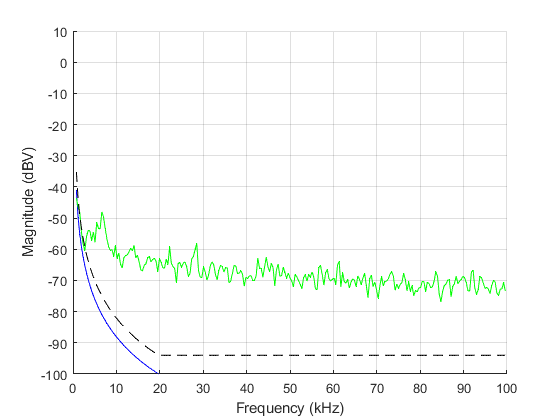

% MatLab 2021 compatible

% Macros
ADC_CHANNELS         = 3;
FFT_BATCH_SIZE       = 512;
REGION               = 1;
ADC_SAMPLE_FREQUENCY = 240000;
COLLECT_DATA         = false;

% Declare path to data dir
region_dir = 'C:/Users/evanr/OneDrive - Texas State University/General - GRP-EE4331-ML-Localization-Project/Workspace/DataExtraction/Raw';
region_dir = sprintf(region_dir,REGION);

% Hard coded COM port selection
clear com_port;
com_port = serialport("COM13",4000000); %, 'timeout', 20.0);

% Make region dir
if ~isfolder(region_dir)
    mkdir(region_dir)
end

% Write header to CSV files
csv_header = ["Freq","Ch1_Mag","Ch2_Mag","Ch3_Mag","Region"];

reg1_dir = sprintf(strcat(region_dir,'/Region_%d_Data.csv'),REGION);

try
    writematrix(csv_header,reg1_dir)
catch
    disp("Error writing header")
end

% Setup figure for displaying fft data.
figure;
ylim([-100 10]);
xlabel("Frequency (kHz)");
ylabel("Magnitude (dBV)");
title("")
set(gcf,'Visible','on')

x_freqs = 2 * 200/(FFT_BATCH_SIZE):200/(FFT_BATCH_SIZE):100 - 200/(FFT_BATCH_SIZE);
start_bytes = 0;

% Init variables
noise_floor = zeros(1, FFT_BATCH_SIZE / 2) - 100;
noise_floor_samples = 0;
noise_floor_offset_db = 6;

while ( 1 )
    %sync with data
    start_bytes = 0;
    while (start_bytes < 4)
        start_byte = read( com_port, 1, "uint8" );
        if ( start_byte == 0x55 )
            start_bytes = start_bytes + 1;
        else
            start_bytes = 0;
        end
    end
    
    fft_data  = read( com_port, ADC_CHANNELS * FFT_BATCH_SIZE / 2, "single" );
    fft_one   = fft_data(1:256);
    fft_two   = fft_data(257:512);
    fft_three = fft_data(513:768);
    
    if COLLECT_DATA

        % Transpose data
        fft_one_transposed   = transpose(fft_one);
        fft_two_transposed   = transpose(fft_two);
        fft_three_transposed = transpose(fft_three);
    
        % Write channel data to CSV
        for idx=1:length(fft_one_transposed)
            
            % Calc bin freq
            freq = (idx-1) * (ADC_SAMPLE_FREQUENCY / 2) / (FFT_BATCH_SIZE / 2);
    
            row = [freq,fft_one_transposed(idx),fft_two_transposed(idx),fft_three_transpoed(idx),REGION];
            writematrix(row,ch1_dir,'WriteMode','append');
        end

    end

    %fft_four = fft_data(769:1024);
    %fft_five = fft_data(1025:1280);
    %fft_six  = fft_data(1281:1536);
    
    if ( noise_floor_samples < 20 )
       for index = 1 : FFT_BATCH_SIZE / 2
           if fft_one(index) > noise_floor(index)
               noise_floor(index) = fft_one(index);
           end
           if fft_two(index) > noise_floor(index)
               noise_floor(index) = fft_two(index);
           end
       end        
       noise_floor_samples = noise_floor_samples + 1;
    end
    
    cla;
    hold on
    grid on
    
    plot( x_freqs, fft_one(3:256), "-r"); 
    plot( x_freqs, fft_two(3:256), "-b");
    plot( x_freqs, fft_three(3:256), "-g"); 
    %plot( x_freqs, fft_four(3:256), "-b");
    %plot( x_freqs, fft_five(3:256), "-m"); 
    %plot( x_freqs, fft_six(3:256), "-y"); 
    plot( x_freqs, noise_floor(3:256) + 6, "--k");

    drawnow;

end


clear com_port